%function [Knuckle,Strut] = Lotus_AARM(z,ChassiHP,KnuckleHP,StrutIn)

ChassiHP=[[-254	-940.085	549.417];[-254	-674.109	542.508];[-254	-948.86	426.15];[-254	-650	400]];
StrutIn=[[-288.53	-800	890.5];[-486.04	-791.31	422.55]];
KnuckleHP=[[-553.6	-786.71	386.62];[-569.05	-806.64	244.84]];
TieRodIn=[[-205.446	-995.732	506.1434];[-553.137	-867.372	303.7852]];
WheelSpindle=[-563.9	-800	289.78];


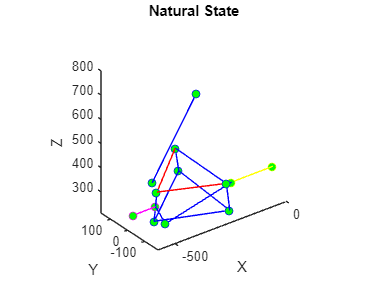


%Natural State
Plot_Suspension(ChassiHP,KnuckleHP,StrutIn,TieRodIn,'Natural State','blue',[(KnuckleHP(1,:)+KnuckleHP(2,:))/2;((KnuckleHP(1,:)+KnuckleHP(2,:))/2 + [-100 0 0])])


%Pushed Down
z1=-100

z1 = -100

delx=20;

[Knuckle,Strut] = Lotus_AARM(z1,ChassiHP,KnuckleHP,StrutIn);

Conversion to logical from sym is not possible.

Error in Lotus_AARM (line 76)
        if zq1(i)<zp && xp1(i)<xu1 && xp1(i)<xu2

[TieRod,WheelCenter,~] = Lotus_TieROD(TieRodIn,KnuckleHP,Knuckle,delx);
Plot_Suspension(ChassiHP,Knuckle,Strut,TieRod,'Pushed Down','cyan',WheelCenter)
hold on

%Lifted Up
z1=200
delx=-20;

[Knuckle,Strut] = Lotus_AARM(z1,ChassiHP,KnuckleHP,StrutIn);
[TieRod,WheelCenter,~] = Lotus_TieROD(TieRodIn,KnuckleHP,Knuckle,delx);
Plot_Suspension(ChassiHP,Knuckle,Strut,TieRod,'Lifted Up','blue',WheelCenter)


hold off

